% Lab 4 – Task 1a: testing the accelerometer
clear all
close('all')
ports = serialportlist;
pb = PyBench(ports(end));  % create a PyBench object

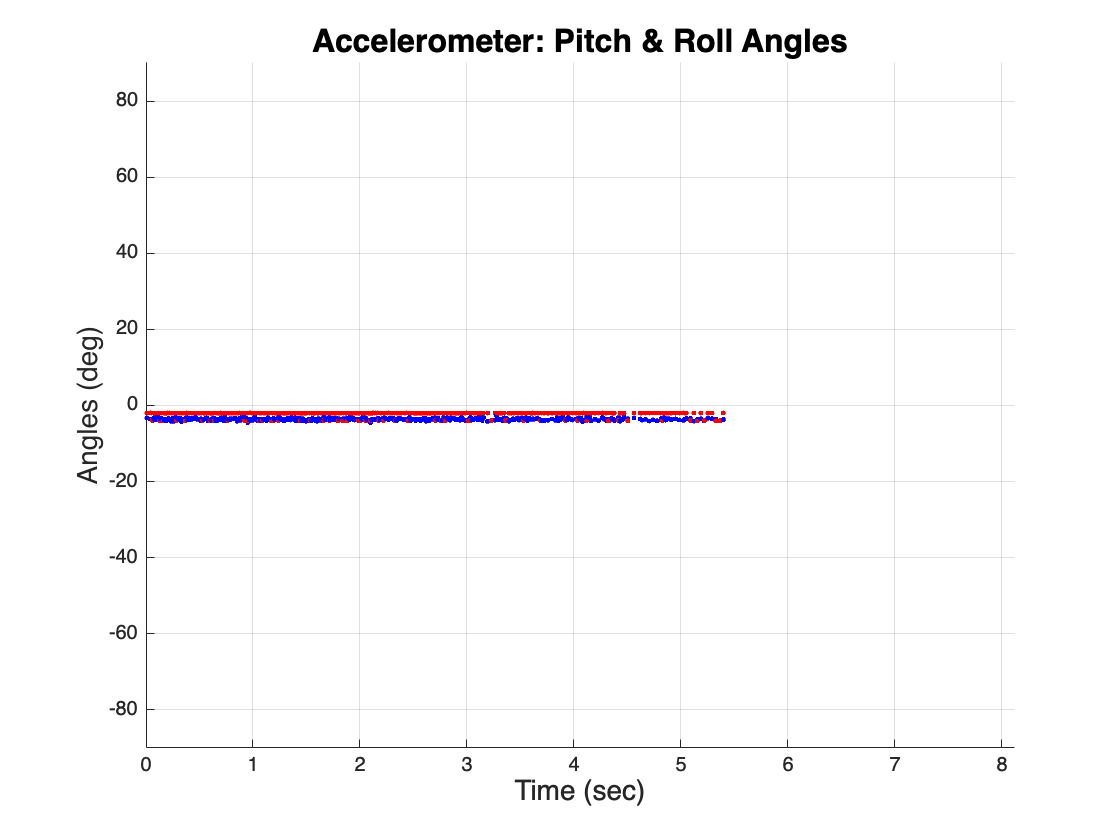

N = 500;  % each graph is 500 time points
end_time = 10.0; % initial guess of time axis range

while true
    % Plot the axes first for plot later
    figure(1)
    clf(1)
    axis([0 end_time -90 90]);
    title('Accelerometer: Pitch & Roll Angles','FontSize', 16);
    ylabel('Angles (deg)','FontSize', 14);
    xlabel('Time (sec)','FontSize', 14);
    grid on; hold on;
    tic;
    
    % read and plot accelerometer data
    for i = 1:N
        [p, r] = pb.get_accel();  % in radians
        timestamp = toc;
        pitch = p * 180 / pi;  % convert to degrees
        roll = r * 180 / pi;
        plot(timestamp, pitch, '.b');  % plot pitch in blue
        plot(timestamp, roll, '.r');  % plot roll in red
        pause(0.001);  % delay for 1 ms
    end  % for loop
    end_time = toc;  % use actual time range from now on
end  % while